files = dir('*.mat');
loadnames = strings(length(files), 1);
for i = 1:length(files)
    loadname = strrep(files(i).name,".mat", "");
    loadnames(i) = loadname;
    data.(loadname) = load(files(i).name);
end 

X

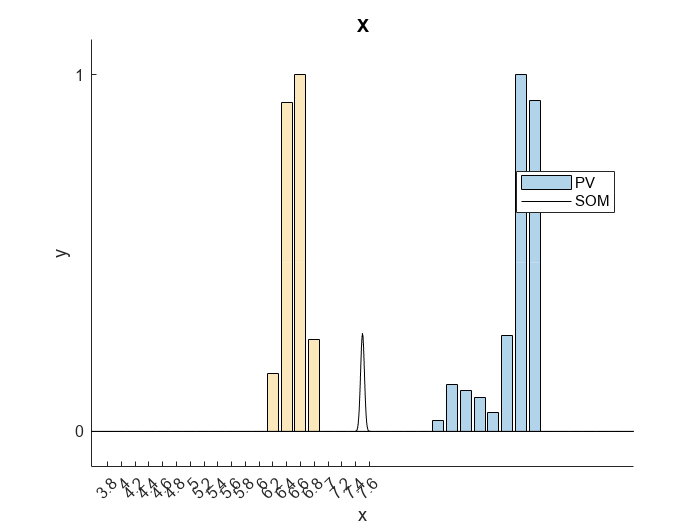

xfig = figure;
hold on
for name = 1:length(loadnames)
    new = data.(loadnames(name)).x_histo_values_combined_normalized_mean;
    b = bar(new); % Use barh for horizontal bars
    b.FaceAlpha = 0.3;
    %gaussian
    s = 1:length(new);
    gaussEq = 'a*exp(-((x-b)^2)/(2*c^2))';
    f = fit(s(:), new(:), gaussEq, 'StartPoint', [max(new), mean(s), std(new)]);
    plot(f, 'k');
end

ylim([-0.1 1.1]);
yticks([0 1]);

% Process y_bin_edges to make it increment from top to bottom
bin_centers = data.(loadnames(name)).x_bin_edges;
bin_centers = round(bin_centers / 1000, 1);
xticks(1:length(bin_centers));
xticklabels(bin_centers);
legend(loadnames, 'Location', 'best');
title("X");
hold off;

Y

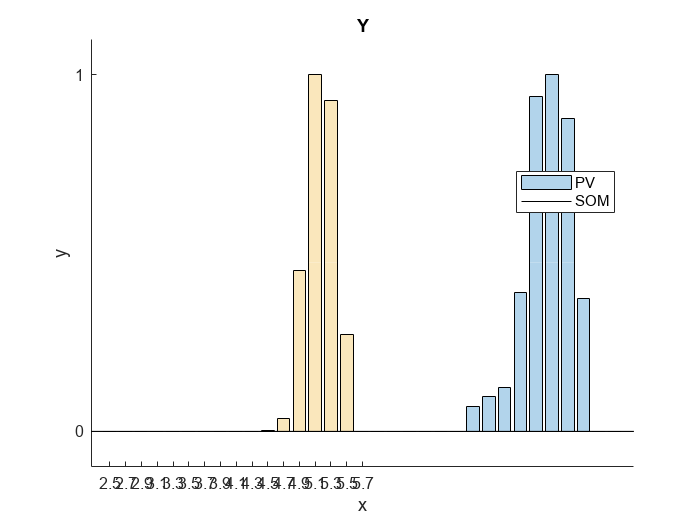

yfig = figure;
hold on
for name = 1:length(loadnames)
    new = data.(loadnames(name)).y_histo_values_combined_normalized_mean;
    b = bar(new); % Use barh for horizontal bars
    b.FaceAlpha = 0.3;
    %gaussian
    s = 1:length(new);
    gaussEq = 'a*exp(-((x-b)^2)/(2*c^2))';
    f = fit(s(:), new(:), gaussEq, 'StartPoint', [max(new), mean(s), std(new)]);
    plot(f, 'k');
end

ylim([-0.1 1.1]);
yticks([0 1]);

% Process y_bin_edges to make it increment from top to bottom
bin_centers = data.(loadnames(name)).y_bin_edges;
bin_centers = round(bin_centers / 1000, 1);
xticks(1:length(bin_centers));
xticklabels(bin_centers);
legend(loadnames, 'Location', 'best');
title("Y");
hold off;

Z

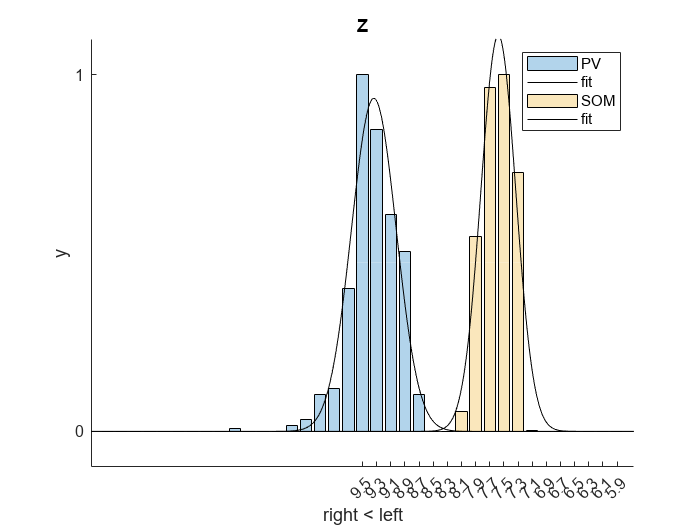

zfig = figure;
hold on
for name = 1:length(loadnames)
    new = data.(loadnames(name)).z_histo_values_combined_normalized_mean;
%     if name == 1
%         new = flip(new)
%     end
    b = bar(new);
    b.FaceAlpha = 0.3;
    %gaussian
    s = 1:length(new);
    gaussEq = 'a*exp(-((x-b)^2)/(2*c^2))';
    f = fit(s(:), new(:), gaussEq, 'StartPoint', [max(new), mean(s), std(new)]);
    plot(f, 'k');
end
ylim([-0.1 1.1]);
yticks([0 1]);
bin_centers = data.(loadnames(name)).z_bin_edges;
bin_centers = round(bin_centers/1000, 1);
xticks(1:length(bin_centers))
xticklabels(bin_centers);
legend(loadnames(1), 'fit', loadnames(2), 'fit');
title("Z")
set(gca, 'XDir', 'reverse')
xlabel('right < left')
hold off

rbp4 = load("Trace6.mat");

Error using load
'Trace6.mat' is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\davis\OneDrive\Desktop\heatmAPP_V2\data\comparisons\trace6_trace17

Change the MATLAB current folder or add its folder to the MATLAB path.

sst = load("Trace17.mat");
[h, p, ci, stats] = ttest2(rbp4.x_data_combined, sst.x_data_combined);
p
[h, p, ci, stats] = ttest2(rbp4.y_data_combined, sst.y_data_combined);
p
[h, p, ci, stats] = ttest2(rbp4.z_data_combined, sst.z_data_combined);
p